# Project 2) Content addressable memory

In this project, you will simulate **content addressable memory (CAM)**, a key differentiator between how data in memory is retrieved from human and computer memory. You will investigate CAM in ART-based systems and in a Hopfield network that uses **Hebbian learning**, a local and ubiquitous learning law used throughout the nervous system. 

You will implement the following models in this project:

- Fuzzy ART (MATLAB) (this notebook)

- Hopfield network (Python) (hopfield.ipynb)

## Task 1) Fuzzy ART

You will implement the unsupervised learning version of Fuzzy ARTMAP (Fuzzy ART), which does not have a teaching signal to help it learn the structure of the data (i.e. categories are not given to the network, even if they are known).

You will use Fuzzy ART to do **unsupervised learning** of the [MNIST handwritten digit dataset.](http://yann.lecun.com/exdb/mnist/) The dataset consists of 60,000 training instances and 10,000 test instances. Each datasample is a 28x28 grayscale image of a handwritten digit between 0-9 (10 classes). Your goal will be to develop "memories" of what each digit (class) based on how the network learns the patterns. Then you will use noisy or incomplete images of the same digits to try and retrieve the appropriate memory. For example, if we present the network with image of a 5 where 80% of the pixels have been corrupted with random noise, can the network "know" it's a 5 and retrieve the 5 from its memory? Tests like these focus on content addressable memory access.

You will also explore how the categories learning via unsupervised learning map onto the actual digits classes (i.e. does the representation of many different 3s look like a 3? How do the self-organized digit categories relate to the actual categories?).

### 1a. Implement fuzzy ART training (`fuzzy_art_train.m`)

To implement Fuzzy ART, it's probably easiest to modify a COPY of your Fuzzy ARTMAP implementation.

- Download the template for `fuzzy_art_train.m` and copy-paste the contents of your Fuzzy ARTMAP code into it. The function signature should be: 

`function [C, w_code] = fuzzy_art_train(data, verbose, varargin)`

Here is a summary of the Fuzzy ART algorithm. Make the required changes to your code to implement it.

- Complement code your data.

- Initialize your coding unit layer like before.

- For every sample $\vec{A}$ in each epoch, compute the net input (*match score*) to the coding layer according to the new **weber law** choice function: $T_j = \frac{|\vec{A} \wedge \vec{w}_j|}{\alpha + |\vec{w}_j|}$. **Note: **you should make sure that you compute the $T_j$ for both committed and uncommitted nodes. The reason for this is that in Fuzzy ART we commit new coding units if the uncommited match score is better than all the committed ones.

- In descending high-to-low order order, compute the fuzzy AND between the next best match score $T_J$ (note the capital J); could be a committed or uncomitted unit). We have **resonance** if $\frac{|\vec{A} \wedge \vec{w}_J|}{|\vec{A}|} >= \rho$, where $\rho$ is the vigilance, a hyperparameter that we now set in the range [0, 1], otherwise we continue to search the ART search cycle through the other $T_J$. If we pass the resonance test, update the winning coding unit's weights.

- Unlike the supervised learning version, we never can "bomb out" of the search cycle: uncommitted nodes should always provide a fallback for a match. Make sure that you update your code given this new logic of setting `C,` the number of committed coding units.

- Make sure that you remove match tracking from your code.

- Update your CIS plotting function for testing purposes (next section). Specifically, remove parameters relating to classes. Because we don't know the classes to properly color/label the data samples, just make all points and category boxes the same color. *I suggest moving your plotting code to the end of the epoch (so it is only called once) for speed purposes when running the upcoming test code.*

### 1b. Test: Fuzzy ART training

Write test code in the cell below that loads in `cis_x_100.mat` then calls your Fuzzy ART training function and creates a plot of the category boxes (see sample output below).

Use `varargin` to set your hyperparameters to:

- 
$$\alpha = 0.01$$


- 
$$\beta = 1$$


- 
$$\rho = 0.75$$


- Number of epochs: 1

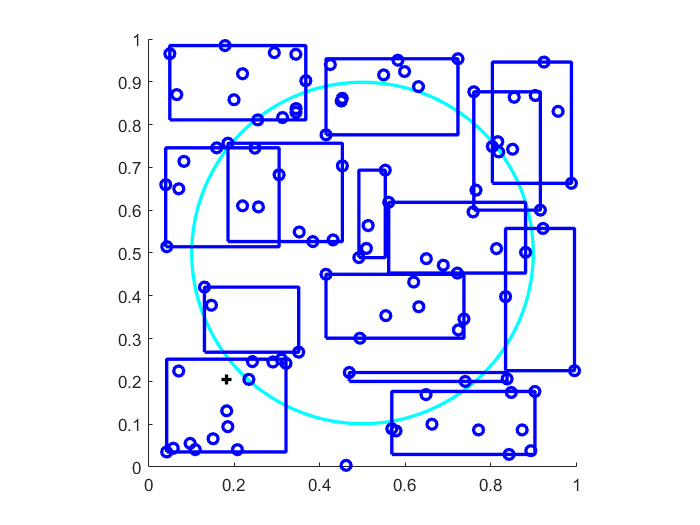

% Write CIS100 training code here
data_x = load("data/cis_x_100.mat");
data_y = load("data/cis_y_100.mat");

data_x = struct2array(data_x);
data_y = struct2array(data_y);

[C, w_code] = fuzzy_art_train(data_x,1,1,1, 'alpha', 0.01, 'beta', 1.0, 'p', 0.75, 'n_epochs', 1);

disp(['Number of committed nodes is ', num2str(C), ' and should be 15.']);

Number of committed nodes is 15 and should be 15.


Your plot should look like (modulo stylistic differences):

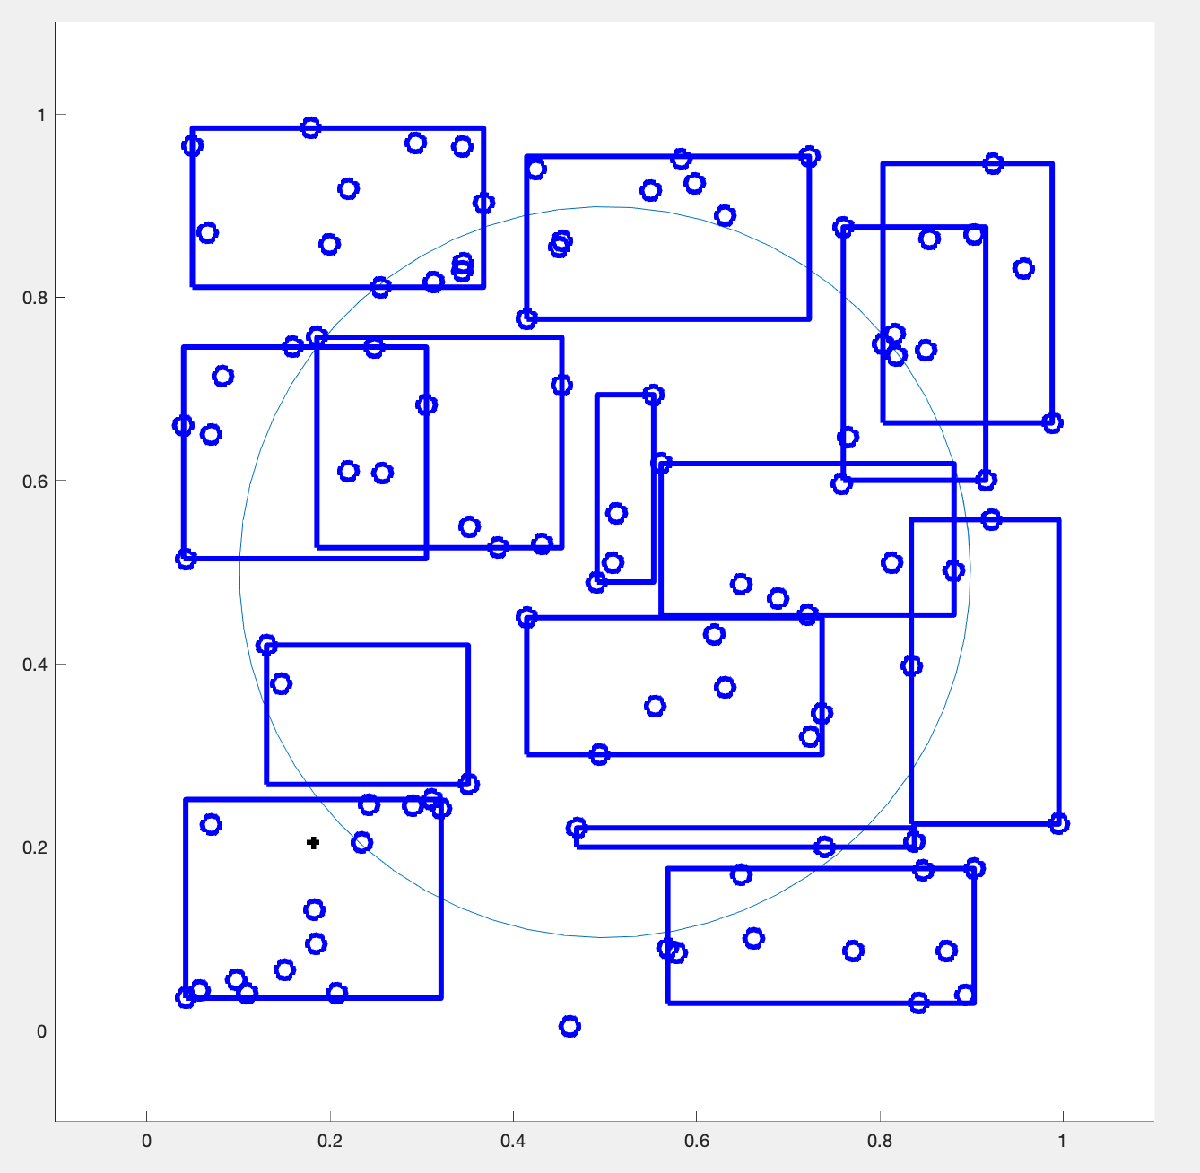

### 1c. Load and preprocess MNIST

- Implement `load_mnist.m` then run the following test code. 

- Below, you should see a 5x10 grid plot of exemplars of each MNIST digit: the SAME digit span each column and digits increase left to right 0->9. (*See example image below*)

mnist_path = 'data/MNIST';
which_set = 'train';
num_exemplars = 5;
num_classes = 10;
do_plot = true;
[mnist_data, mnist_y] = load_mnist(mnist_path, which_set, num_exemplars, num_classes, do_plot);
disp(['MNIST shape is ', num2str(size(mnist_data)), ' and should be 784   50.']);

MNIST shape is 784   50 and should be 784   50.


fprintf('The min/max of one image is %d/%d. and should be 0/1.', min(mnist_data(:,1)), max(mnist_data(:,1)));

The min/max of one image is 0/1. and should be 0/1.

disp(['MNIST classes shape is ', num2str(size(mnist_y)), ' and should be 50   1.']);

MNIST classes shape is 50   1 and should be 50   1.


disp(['The class values are ', num2str(unique(mnist_y))', ' and should be 0123456789']);

The class values are 0123456789 and should be 0123456789


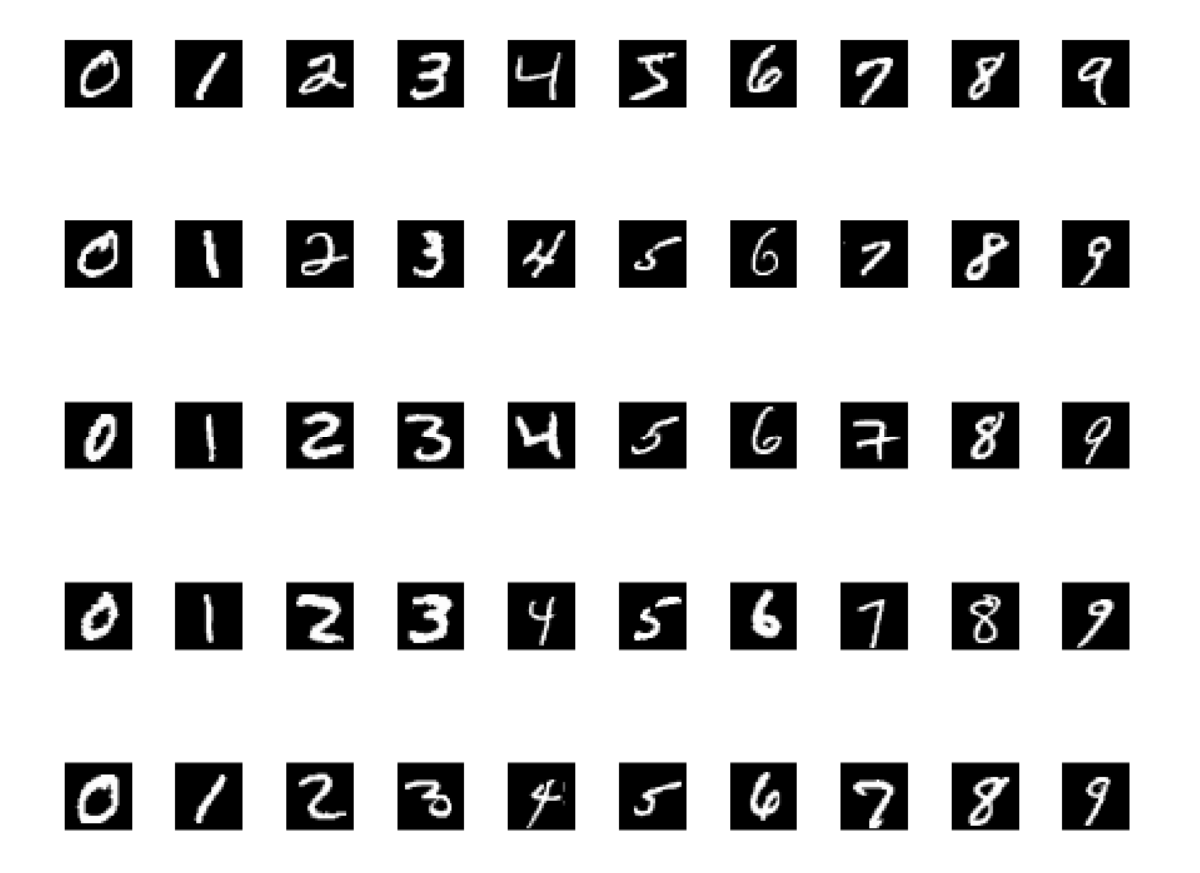

### 1d. Implement Fuzzy ART predict (`fuzzy_art_predict.m`)

- Implement the `fuzzy_art_predict.m` function so that you can present test inputs to a trained Fuzzy ART network and have determine return which coding unit becomes most active. The weights of each most active coding unit are the "memories" that are recalled by the network for that particular data sample. You may use the Fuzzy ARTMAP version as a starting point (copy-paste into new function). The function header should be:

`function c_pred = fuzzy_art_predict(C, w_code, data, verbose, varargin)`

### 1e. Implement main function to train and predict (`run_fuzzy_art_mnist.m`)

This function should load in some number of exemplars for some number of the MNIST digits, train Fuzzy ART, get the activated codes via the predict function, possibly make one plot that shows the all committed units' weights and possibly another that shows the test images next to the recalled "memory". The function header should be:

`function [mnist_test_y, code_inds, C] =  run_fuzzy_art_mnist(mnist_path, sets, num_exemplars, num_classes, noisify_test, erase_test, plot_wts, plot_recall, varargin)`

**Note: **Ignore the `noisify_test` and `erase_test` variables for now (assume they are false/not used).

**Note: **The `varargin` should be passed along to `fuzzy_art_train` (not parsed by `run_fuzzy_art_mnist`). To properly pass `varargin` from one function to another, since it is packaged as a cell array, pass it to `fuzzy_art_train `as `varargin{:} `so that it doesn't create a nested cell array (cell array of a cell array) during the passing process.

`Tip:` At the beginning of your function, check to see if the user passed in any arguments. If not, set default values for everything. This can help reduce the time between runs in the debug cycle (you can just hit "Run" without passing in function parameters).

#### (i) Perfect memory test 1/2: All learned memories

- Finish writing the test code in the following cell that trains and tests on the same data. The data are the first digits in the MNIST train digits (1 exemplar, all 10 classes).

- Set vigilance really high (e.g. to 0.999) to make sure that that each digit will have its own category. This is a sanity check and to set ourselves up for the noise/incomplete data tests coming up. In Task 2, you will explore the representations when the vigilance is lower.

- Set the `noisify_test` and `erase_test` variables to false.

Running the below test code should result in a plot showing the weights for the committed units. There should be 10 panels, ranging from 0 to 9 (exactly the same as the data exemplars).

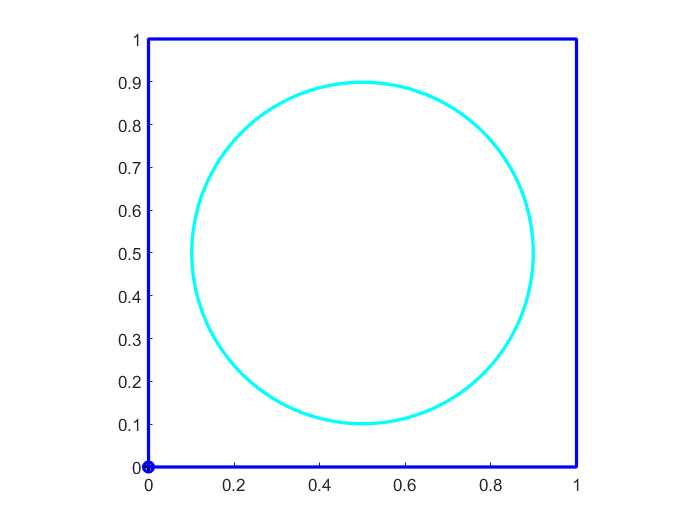

mnist_path = 'data/';
sets = {'train'; 'train'};
num_exemplars = [1 1];
num_classes = 10;
plot_wts = true;
plot_recall = false;
run_fuzzy_art_mnist(mnist_path, sets, num_exemplars, num_classes, ...
    false, false, plot_wts, plot_recall, ...
    'alpha', 0.01, ...
    'beta', 1, ...
    'p', 0.999, ...
    'n_epochs', 1);

#### (ii) Perfect memory test 2/2: Test images and memories retrieved based on them

- Copy-paste your test code from above in the cell below. Set `plot_wts = false;` and `plot_recall = true;`

You should see a plot with 10 rows and 2 columns. The test data exemplars are on the LEFT and the memories obtained from the predict coding unit's weights are on the RIGHT. You should see two identical images in each row (i.e. the network is able to remember each digit perfectly).

### 1f. Hazy memory test: Test on noisy images

Now you are going to make use of the `noisify_test` variable. You will add noise the the test images to stimulate recall of a memories with only partially correct information in the look-up "key".

- If it is set to true, modify your TEST data only (leave the training data alone). Corrupt a proportion of the pixels in EACH image by setting the value of each selected pixel randomly to 0 or 1 ("salt and pepper noise").

- Paste your test code in the cell below, setting `noisify_test = true;`

- You may hard-code the noise proportion in `run_fuzzy_art_mnist`. Set it and create a `plot_recall` plot below showing the **highest level of noise **you are able to add (keeping other parameters the same as before) and still have the network recover the correct memories for all 10 digits. Full credit is given for getting within 0.05 (don't sweat getting the "exact" number).

### 1g. Eraser test: missing information in the test images

- If `erase_test = true`, delete a proportion of the columns in each data image. For simplicity, do this contigously from the left side (e.g. if the proportion = 0.1, the 3 leftmost columns of the image should be black / set to 0). 

- Same objective as above: **Find the smallest proportion that allows perfect recovery of the test images. **Hard-code this and generate a plot below showing this with your test code (be sure to turn noise off for this experiment).

## Task 2) Unsupervised learning of MNIST digits with Fuzzy ART

In this task, you will do unsupervised learning on the MNIST with Fuzzy ART using the "pipeline" that you have developed. The overall objective is to compare the categories that Fuzzy ART learns and compare them to the ground-truth categories. Is there a close mapping between the two? When the network makes mistakes, does it make sense? If Fuzzy ART makes multiple categories for a single digit, do the weights look similar or different (i.e. a "subcategory")?

### 2a. Fast-commit, slow-recode option

First, you will implement and analyze the **fast-commit, slow-recode** option for Fuzzy ART: everytime you commit a new coding unit, update that unit's weights with $\beta=1$. When you update the weights for any previously committed coding unit, set the weight to $\beta < 1$.

- Implement support for the fast-commit, slow recode option. Allow the user to turn this mode on with a boolean flag (default is false). 

- Add `varargin` support so that the user can turn on the mode to override the default post-commit $\beta$ value.

- In the two cells below, adapt your evolving test code. Train for 25 epochs with 10 exemplars per class in the training set and 1 exemplar per class with the test set (all 10 digits in both cases). Set the vigilance to 0.85. In the 1st cell, turn ON fast-commit, slow recode with $\beta = 0.1$post-commit. In the 2nd cell, turn OFF fast-commit, slow recode, keeping everything else the same.

- Generate FOUR plots in total: two grid plots of all the weights for all committed units (i.e. the categories) when the mode is on or off, and two 2 column plots showing the test samples next to the predicted memory.

run_fuzzy_art_mnist("data/MNIST", {'train', 'test'}, [10 1], 10, 0, 0, 0, 0, 'beta', 0.1, 'fast', 1)
disp(['Number of categories created: ', num2str(C)]);

run_fuzzy_art_mnist("data/MNIST", {"train", "test"}, [10 1], 10, 0, 0, 0, 0, 'fast', 0)
disp(['Number of categories created: ', num2str(C)]);

**Question 1: **Which set of learned category weights seem better to you? Why?

**Question 2: **What are the total number of categories learned in both cases? Why do you think these values turned out like this (i.e. if they are the same, why are they? If they are different, why are they and why might one be larger than the other)?

**Answer 1:**

**Answer 2:**

### 2b. Vigilance and categories

- With the same configuration/scenario (keep fast-commit, slow-recode turned on), test out a few values for $\rho$ in the range [0, 1].

mnist_path = 'data/MNIST';
sets = {'train'; 'test'};
num_exemplars = [10, 1];
num_classes = 10;
plot_wts = true;
plot_recall = false;
run_fuzzy_art_mnist(mnist_path, sets, num_exemplars, num_classes, ...
    false, false, plot_wts, plot_recall, ...
    'alpha', 0.01, ...

    'beta', 1, ...

Number of categories created: 15


Index in position 2 exceeds array bounds (must not exceed 10).

Error in fuzzy_art_predict (line 37)
      Tj = choiceByWeber(A(:, i), w_code, alpha);

Error in run_fuzzy_art_mnist (line 53)
  c_pred = fuzzy_art_predict(C, w_code, test, 1);

    'p', 0, ...
    'n_epochs', 25);

Increase p
mnist_path = 'data/';
sets = {'train'; 'test'};
num_exemplars = [10, 1];
num_classes = 10;
plot_wts = true;
plot_recall = false;
run_fuzzy_art_mnist(mnist_path, sets, num_exemplars, num_classes, ...
    false, false, plot_wts, plot_recall, ...
    'alpha', 0.01, ...
    'beta', 1, ...
    'p', 0.3, ...
    'n_epochs', 25);

mnist_path = 'data/';
sets = {'train'; 'test'};
num_exemplars = [10, 1];
num_classes = 10;
plot_wts = true;
plot_recall = false;
run_fuzzy_art_mnist(mnist_path, sets, num_exemplars, num_classes, ...
    false, false, plot_wts, plot_recall, ...
    'alpha', 0.01, ...
    'beta', 1, ...
    'p', 0.6, ...
    'n_epochs', 25);

mnist_path = 'data/';
sets = {'train'; 'test'};
num_exemplars = [10, 1];
num_classes = 10;
plot_wts = true;
plot_recall = false;
run_fuzzy_art_mnist(mnist_path, sets, num_exemplars, num_classes, ...
    false, false, plot_wts, plot_recall, ...
    'alpha', 0.01, ...
    'beta', 1, ...
    'p', 1, ...
    'n_epochs', 25);

**Question 3: **Describe the effect of $\rho$ on the number of categories formed. What does it mean for category learning?

**Answer 3:**

### 2c. Run an experiment of your own

In the context of unsupervised learning of MNIST with Fuzzy ART, run your own mini-experiment (larger ones *distinct* from what you do here could be an extension). Some ideas for areas to explore are (doesn't need to be one of these):

- Systematically play with and report the effects of another parameter.

- Increase the test set size to > 1 (e.g. 2). Analyze what the predictions/memorizes are compared to the test digits.

- Analyze the category predictions on the test set. For example, the predict function returns the best matching coding units indices. If the predictions are wrong, are there common confusions it makes (e.g. consistently confuse one digit for another)? Interpret the pattern of errors and try to quantify them.

- Explore training on more exemplars and/or more epochs. Interpret and try to quantify what you observe.

You're welcome to take this in any number of directions, but I encourage you to, at least for the core project, stick with small sample sizes so that you can readily gain an intuition of what the network is doing.

For any experiment you chose, write code below to run it to get the results. You can write other function/script files if you like.

For full credit:

- Define your experiment clearly (what question are you trying to address?). Doesn't need to be long, but it should be clear what you're trying to do and why.

- Have one or more plots.

- Interpret the plots with respect to the question you are exploring. Why does the plot/manipulation potentially address it? What is it showing toward that end?